# ODE Lab: Creating your own ODE solver in MATLAB

In this lab, you will write your own ODE solver for the Improved Euler method (also known as the Heun method), and compare its results to those of `ode45`.

You will also learn how to write a function in a separate m-file and execute it.

Opening the m-file lab3.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six (6) exercises in this lab that are to be handed in on the due date. Write your solutions in the template, including appropriate descriptions in each step. Save the .m files and submit them online on Quercus.

## Student Information

Student Name: Robert Purcaru 

Student Number: 1007019842

## Creating new functions using m-files.

Create a new function in a separate m-file:

Specifics: Create a text file with the file name f.m with the following lines of code (text):

Now MATLAB can call the new function f (which simply accepts 3 numbers and adds them together). To see how this works, type the following in the matlab command window: sum = f(1,2,3)

## Exercise 1

Objective: Write your own ODE solver (using the Heun/Improved Euler Method).

Details: This m-file should be a function which accepts as variables (t0,tN,y0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0 is the initial condition of the ODE, and h is the stepsize. You may also want to pass the function into the ODE the way `ode45` does (check lab 2).

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

## Exercise 2

Objective: Compare Heun with `ode45`.

Specifics: For the following initial-value problems (from lab 2, exercises 1, 4-6), approximate the solutions with your function from exercise 1 (Improved Euler Method). Plot the graphs of your Improved Euler Approximation with the `ode45` approximation.

(a) `y' = y tan t + sin t, y(0) = -1/2` from `t = 0` to `t = pi`

(b) `y' = 1 / y^2 , y(1) = 1` from `t=1` to `t=10`

(c) `y' = 1 - t y / 2, y(0) = -1` from `t=0` to `t=10`

(d) `y' = y^3 - t^2, y(0) = 1` from `t=0` to `t=1`

Comment on any major differences, or the lack thereof. You do not need to reproduce all the code here. Simply make note of any differences for each of the four IVPs.

`y' = y tan t + sin t, y(0) = -1/2` from `t = 0` to `t = pi`

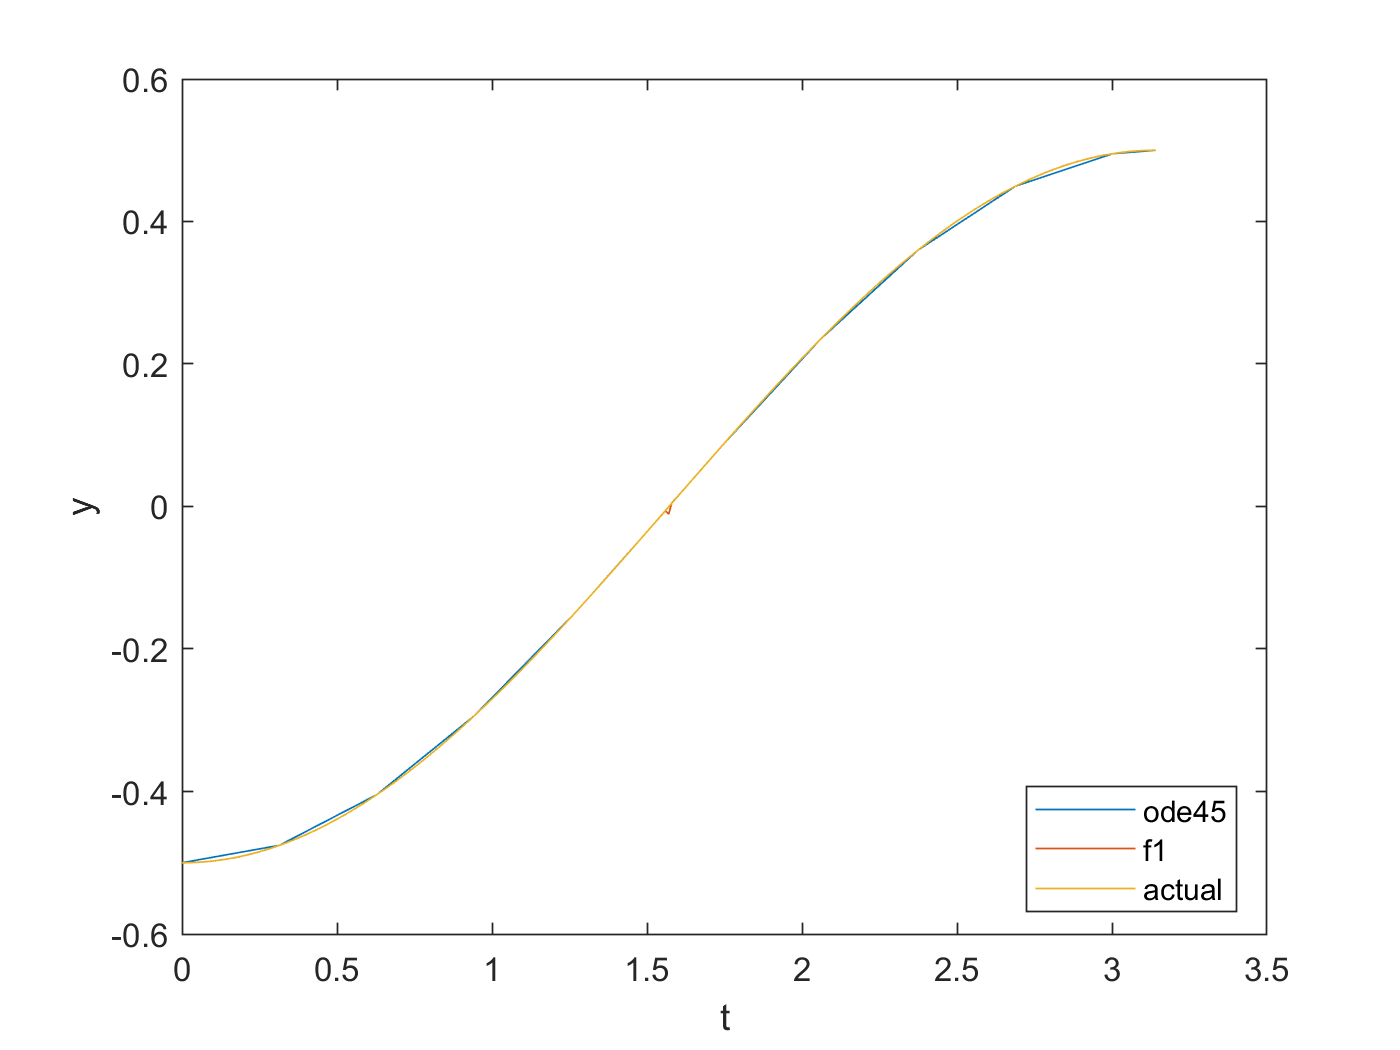

f_2a = @(t,y) y*tan(t) + sin(t);
t0_2a = 0;
t1_2a = pi;
y0_2a = -1/2;

soln_2ai = ode45(f_2a, [t0_2a, t1_2a], y0_2a);
[soln_2aii_x, soln_2aii_y] = f1(f_2a,t0_2a, t1_2a, y0_2a, 0.01);

g_2a = @(t) ((sin(t)).^2).*((2*cos(t)).^-1) - (2.*(cos(t))).^-1;
tt_2a = linspace(0, pi, 100);
yy_2a = g_2a(tt_2a);

plot(soln_2ai.x, soln_2ai.y, soln_2aii_x, soln_2aii_y, tt_2a, yy_2a);
xlabel('t');
ylabel('y');
legend('ode45', 'f1', 'actual', 'Location','Best');

`The ode45 function seems more coarse than the improved euler's method, likely due to the finer step size in the latter. Interestingly, the improved euler's method has a weird drop in slope right where the inaccuracy of the ode45 function is at a maximum. This was discussed in the previous lab but can be seen manifested here.`

`y' = 1 / y^2 , y(1) = 1` from `t=1` to `t=10`

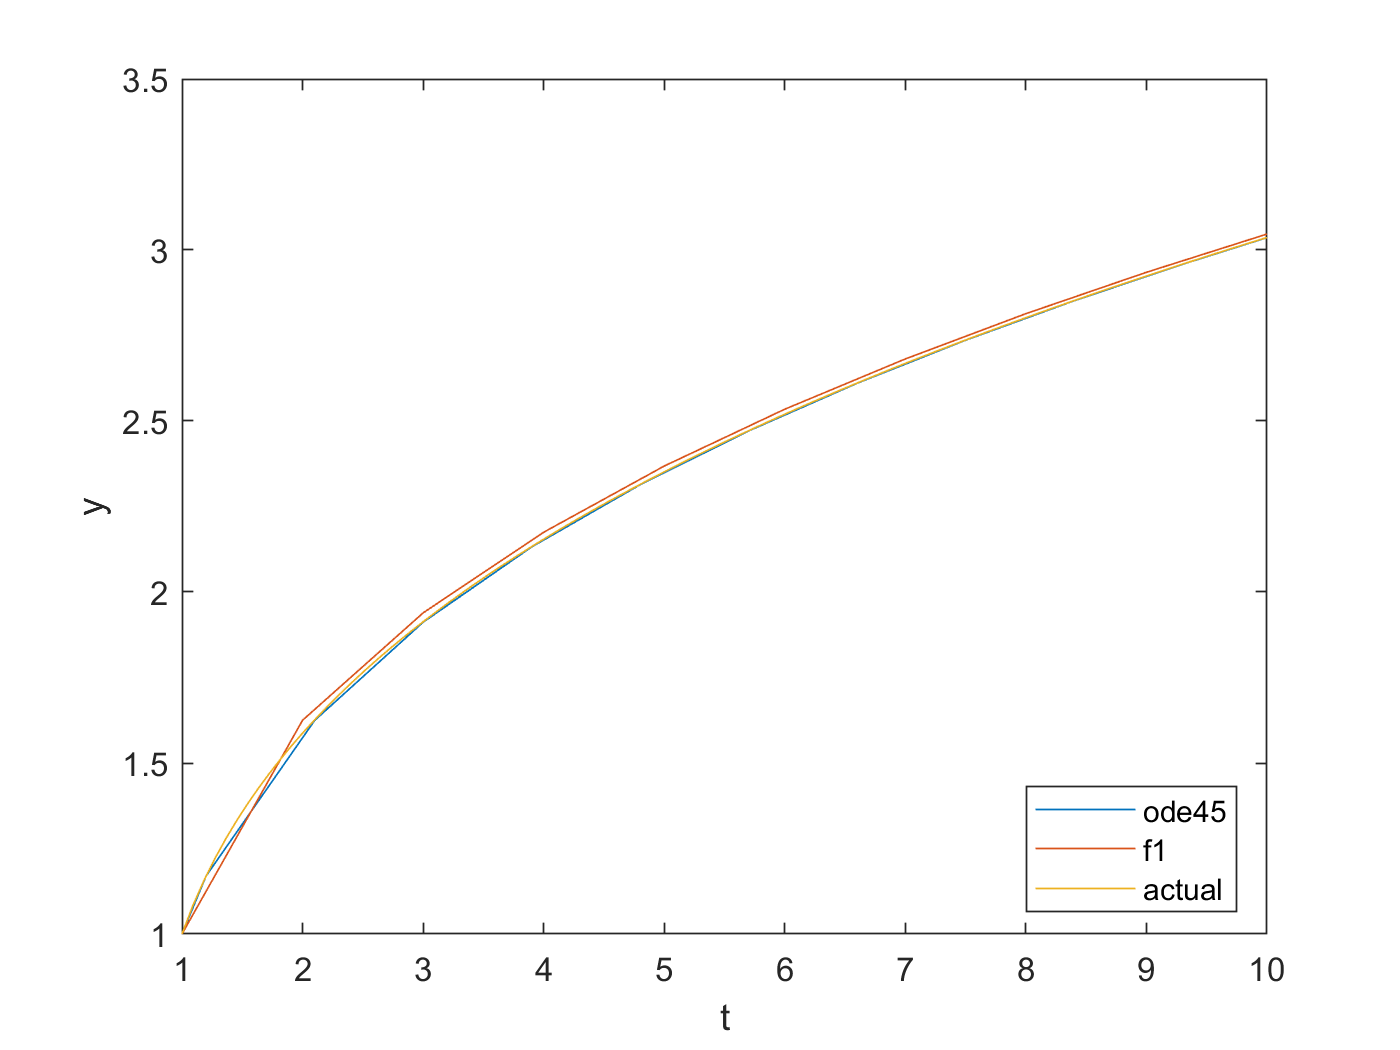

f_2b = @(t,y) 1/(y.^2);
t0_2b = 1;
t1_2b = 10;
y0_2b = 1;

soln_2bi = ode45(f_2b,[t0_2b, t1_2b], y0_2b);
[soln_2bii_x, soln_2bii_y] = f1(f_2b,t0_2b, t1_2b, y0_2b, 1);

g_2b = @(t) (3*t - 2).^(1/3);
tt_2b = linspace(t0_2b, t1_2b, 100);
yy_2b = g_2b(tt_2b);

plot(soln_2bi.x, soln_2bi.y, soln_2bii_x, soln_2bii_y, tt_2b, yy_2b);
xlabel('t');
ylabel('y');
legend('ode45', 'f1', 'actual', 'Location','Best');

`For this one, I made the step size of the improved euler's method more coarse whcih demonstrates one of what seems to be the shortcomings of the improved euler's moethod vs ode45: the improved euler's method doesn't necessarily "correct course" once it strays away from the function whereas the ode45 seems to do so. Still, even with a relatively large step size, both seem to track the function well.`

`y' = 1 - t y / 2, y(0) = -1` from `t=0` to `t=10`

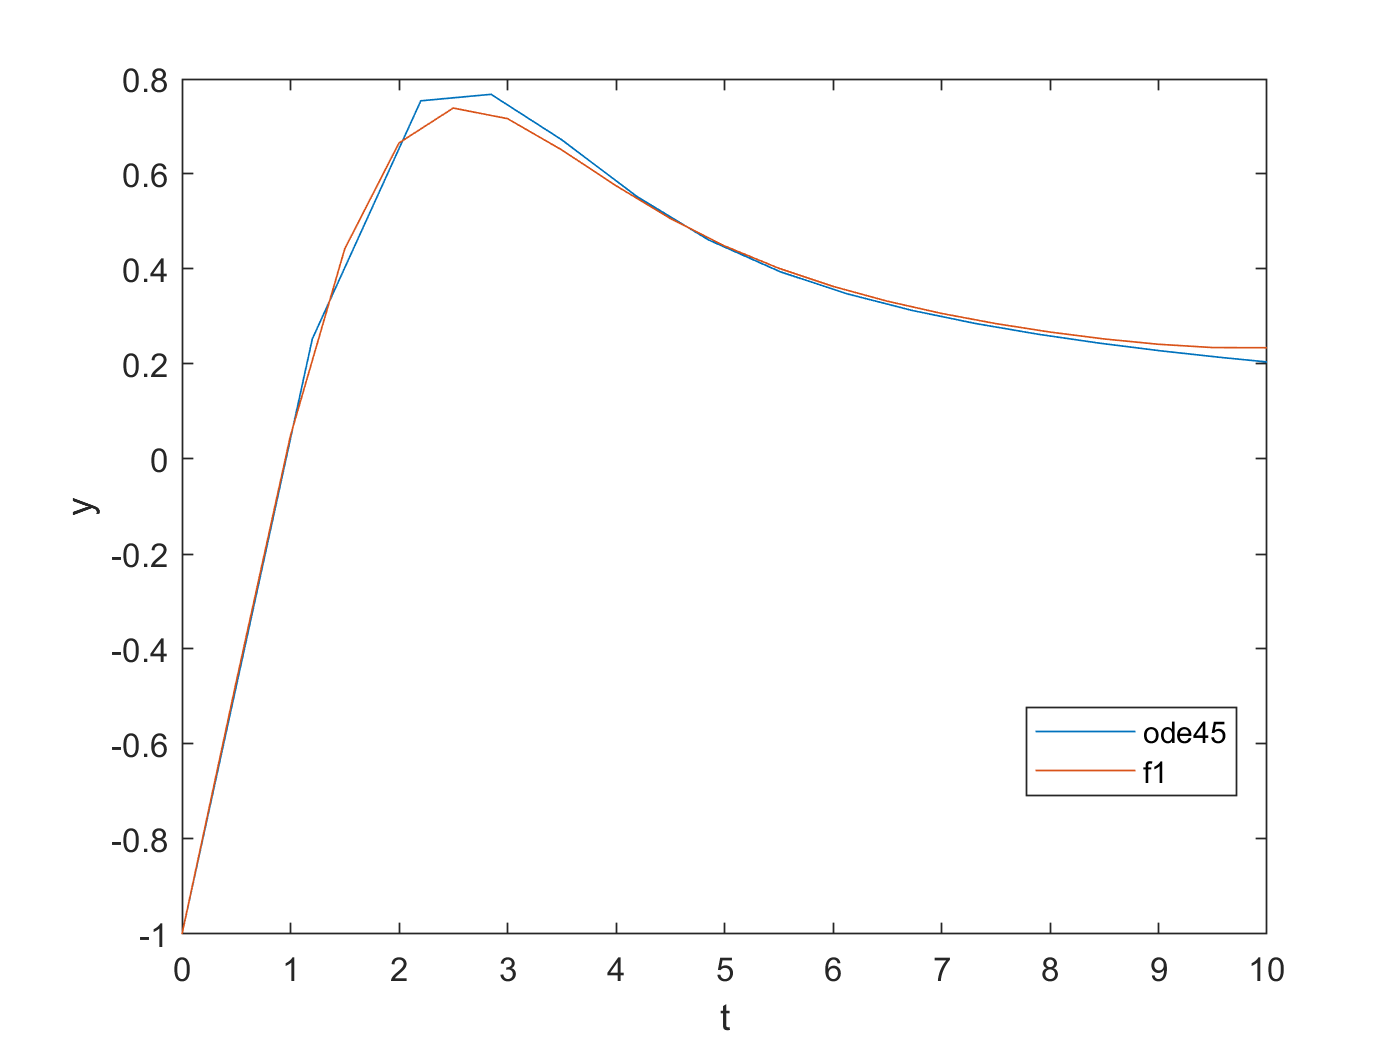

f_2c = @(t,y) 1-(t.*y)./2;
t0_2c = 0;
t1_2c = 10;
y0_2c = -1;

soln_2ci = ode45(f_2c, [t0_2c, t1_2c], y0_2c);
[soln_2cii_x, soln_2cii_y] = f1(f_2c,t0_2c, t1_2c, y0_2c, 0.5);

plot(soln_2ci.x, soln_2ci.y, soln_2cii_x, soln_2cii_y);
xlabel('t');
ylabel('y');
legend('ode45', 'f1', 'Location','Best');

`Here, we see a pretty big difference between ode45 and improved euler's method. First, with a smaller step size, ode45 keeps the maximum around t = 2.5 intact whereas the improved euler's method needs a smaller step size to do the same. The improved euler's method and ode45 also seem to start to diverge beyond t=7 after they cross near t=4.75.`

`y' = y^3 - t^2, y(0) = 1` from `t=0` to `t=1`

f_2d = @(t,y) y.^3 - t.^2

f_2d = function_handle with value:
    @(t,y)y.^3-t.^2


t0_2d = 0;
t1_2d = 1;
y0_2d = 1;
soln_2di = ode45(f_2d, [t0_2d, t1_2d], y0_2d);

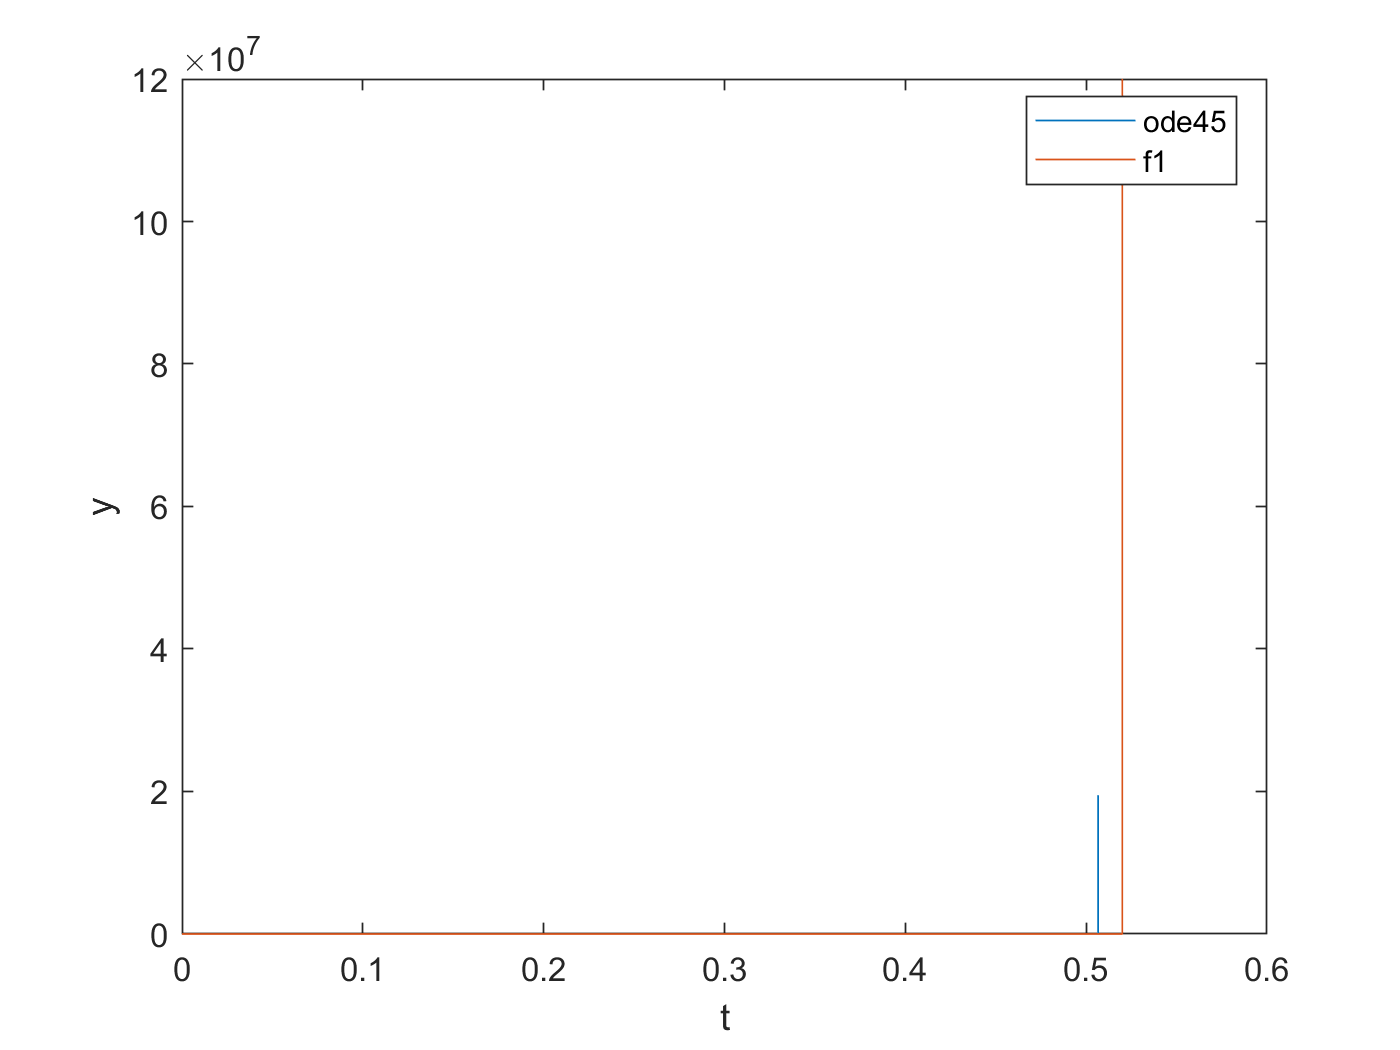

[soln_2dii_x, soln_2dii_y] = f1(f_2d,t0_2d, t1_2d, y0_2d, 0.01);

plot(soln_2di.x, soln_2di.y, soln_2dii_x, soln_2dii_y);
ylim([0 120000000]);
xlabel('t');
ylabel('y');
legend('ode45', 'f1', 'Location','Best');

In this one, the improved euler's method doesn't seem to react to the asymtote around t=0.51 like the ode45 function does. This might be due to the rate at which the slope of the function changes as t approaches 0.5. If the slope changes realtively abruptly , it is possible that the improved euler's method overshoots that point that ode45 is tracking until close to 0.52 where it jumps up after the slope hits that asymptote. This could be dealt with by making the step size smaller until the amount that improved euler's method overshoots by is smaller.

## Exercise 3

Objective: Use Euler's method and verify an estimate for the global error.

Details: 

(a) Use Euler's method (you can use euler.m from iode) to solve the IVP

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

from `t=0` to `t=0.5`.

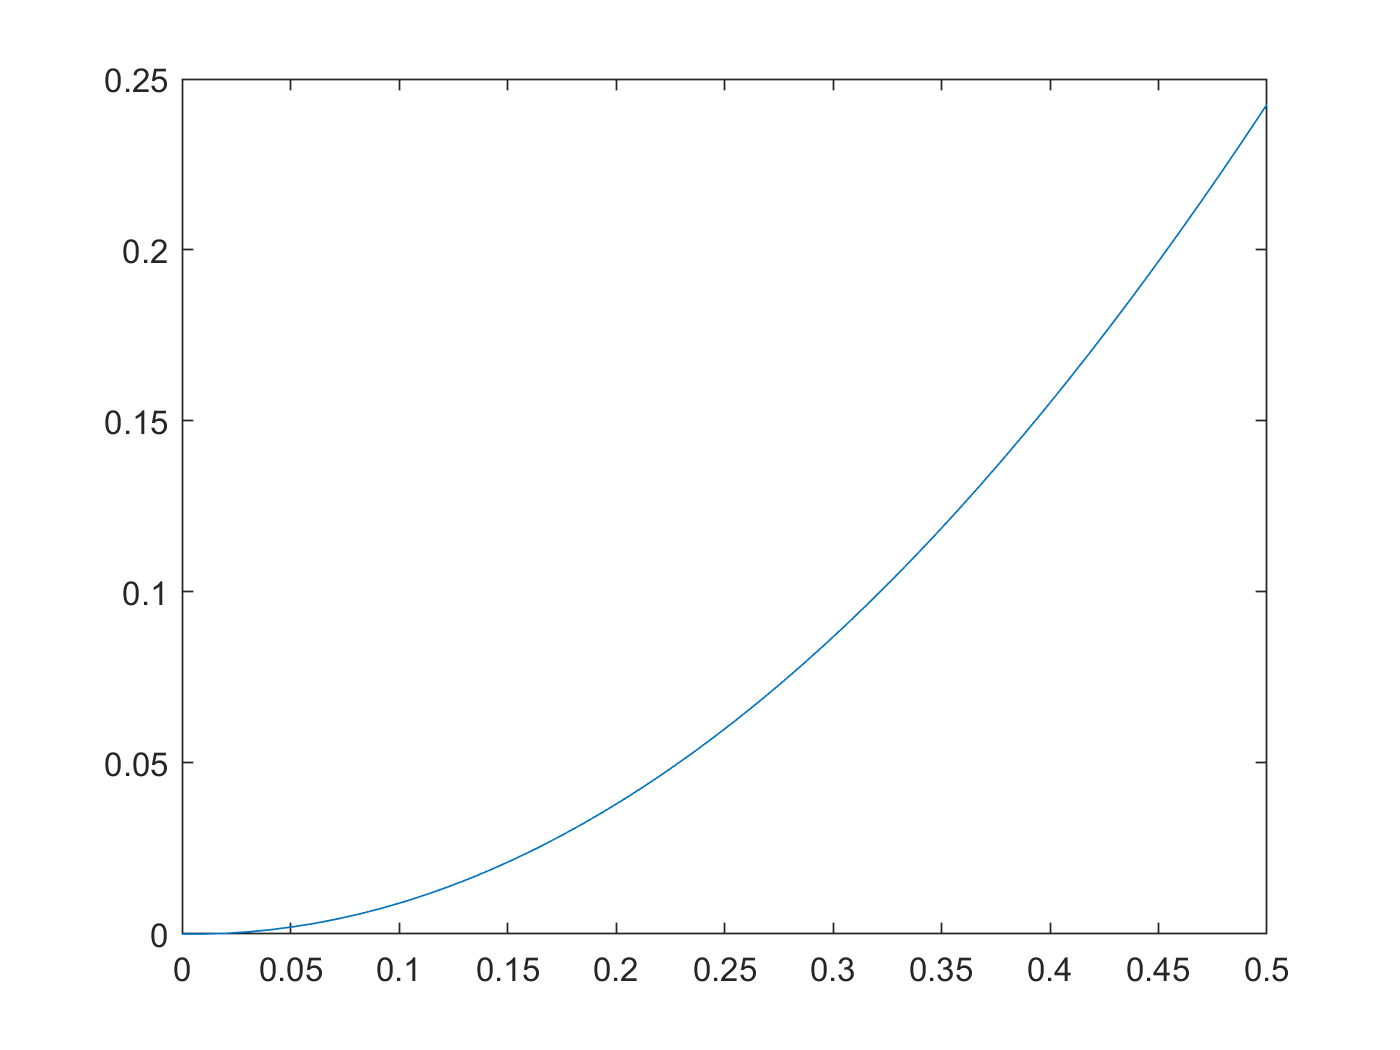

h=0.01;
f3a = @(t,y) 2 .* t .* sqrt( 1 - y.^2 );
t_3a = linspace(0, 0.5, 0.5/h);
soln3a = euler(f3a, 0, t_3a);

plot(t_3a, soln3a);

(b) Calculate the solution of the IVP and evaluate it at `t=0.5`.

    General solution: y = sin(t^2 + c)

    Particular solution: y= sin(t^2)

soln3b = @(t) sin(t.^2);
actual_soln = soln3b(0.5)

actual_soln = 0.2474

(c) Read the attached derivation of an estimate of the global error for Euler's method. Type out the resulting bound for En here in a comment. Define each variable.

    En = |`y_(n+1) - phi_(n+1)`|                       

    En ~ (1+M)/2 * delta(t) (M * delta(t)n)                 

    partial_t (`2 t sqrt(1-y^2)`) = 2sqrt(1-y^2)

    partial_y(2 t sqrt(1-y^2)) = -4ty(1-y^2)^(-1/2) 

partial_t = @(y) 2*sqrt(1-y.^2);
partial_y = @(t,y) -4.*t.*y.*(1-y.^2).^(-1/2);

y_bounds = linspace(-1, 1, length(t_3a));

max_f = max(soln3b(t_3a))

max_f = 0.2474

max_p_t = max(partial_t(y_bounds))

max_p_t = 1.9996

max_p_y = max(partial_y(t_3a, y_bounds))

max_p_y = 0.3001

Note I'm going to use 2 here because for more fine y values, M -> 2 for max_p_t

delta_t = 0.01;
M = 2;
n = length(t_3a);
En = (1+M)/2 * delta_t * M * delta_t * n

En = 0.0150

     En is global error at n, 

    M is upper bound on f, the partial of f wrt t and the partial of f wrt y.

    t is time

    n is increment of interest

    y_(n+1) is next approximation

    phi_(n+1) is actual solution at t + increment

(d) Compute the error estimate for `t=0.5` and compare with the actual error

actual_error = abs(soln3a(end) - actual_soln)

actual_error = 0.0048

(e) Change the time step and compare the new error estimate with the actual error. Comment on how it confirms the order of Euler's method.

if we change the time step we can confirm the Euler's method is linear becasue the error follows linearly with the solution

## Adaptive Step Size

As mentioned in lab 2, the step size in `ode45` is adapted to a specific error tolerance.

The idea of adaptive step size is to change the step size `h` to a smaller number whenever the derivative of the solution changes quickly. This is done by evaluating f(t,y) and checking how it changes from one iteration to the next.

## Exercise 4

Objective: Create an Adaptive Euler method, with an adaptive step size `h`.

Details: Create an m-file which accepts the variables `(t0,tN,y0,h)`, as in exercise 1, where `h` is an initial step size. You may also want to pass the function into the ODE the way `ode45` does.

Create an implementation of Euler's method by modifying your solution to exercise 1. Change it to include the following:

(a) On each timestep, make two estimates of the value of the solution at the end of the timestep: `Y` from one Euler step of size `h` and `Z` from two successive Euler steps of size `h/2`. The difference in these two values is an estimate for the error.

(b) Let `tol=1e-8` and `D=Z-Y`. If `abs(D)<tol`, declare the step to be successful and set the new solution value to be Z-D. This value has local error `O(h^3)`. If `abs(D)>=tol`, reject this step and repeat it with a new step size, from (c).

(c) Update the step size as `h = 0.9*h*min(max(tol/abs(D),0.3),2)`.

Comment on what the formula for updating the step size is attempting to achieve.

By decreasing the step size, we are "staying closer" to the function when we follow the tangent at a given point. Since the function is not actually linear at the point we are interested in but our approximation is linear, we want to take as small steps as practical so the function behaves more linearly over the given step. When we compute the error D, we are seeing if the rate at which the function is curving away from our line is large enough to cause an error between a single step and a double step approximation that is greater than our tollerance.

## Exercise 5

Objective: Compare Euler to your Adaptive Euler method.

Details: Consider the IVP from exercise 3.

(a) Use Euler method to approximate the solution from `t=0` to `t=0.75` with `h=0.025`.

f5a = @(t,y) 2 .* t .* sqrt( 1 - y.^2 );
t_5a = linspace(0, 0.75, 30);
soln5a = euler(f3a, 0, t_5a);

(b) Use your Adaptive Euler method to approximate the solution from `t=0` to `t=0.75` with initial `h=0.025`.

[soln_5b_x, soln_5b_y] = f4(f5a, 0, 0.75, 0, 0.025)

soln_5b_x =          0    0.0250    0.0500    0.0750    0.1000    0.1250    0.1500    0.1712    0.1859    0.2005    0.2152    0.2265    0.2378    0.2491    0.2604    0.2699    0.2795    0.2890    0.2986    0.3069    0.3152    0.3236    0.3319    0.3403    0.3473    0.3544    0.3615    0.3685    0.3756    0.3826    0.3897    0.3959    0.4022    0.4084    0.4147    0.4209    0.4272    0.4334    0.4390    0.4445    0.4501    0.4556    0.4612    0.4667    0.4723    0.4778    0.4834    0.4882    0.4930    0.4978


soln_5b_y =          0    0.0006    0.0025    0.0056    0.0100    0.0156    0.0214    0.0260    0.0312    0.0369    0.0415    0.0465    0.0518    0.0572    0.0621    0.0671    0.0724    0.0778    0.0827    0.0877    0.0929    0.0982    0.1036    0.1083    0.1131    0.1181    0.1231    0.1282    0.1334    0.1387    0.1435    0.1483    0.1533    0.1583    0.1633    0.1685    0.1737    0.1784    0.1832    0.1880    0.1929    0.1978    0.2028    0.2078    0.2129    0.2180    0.2225    0.2271    0.2317    0.2363


(c) Plot both approximations together with the exact solution.

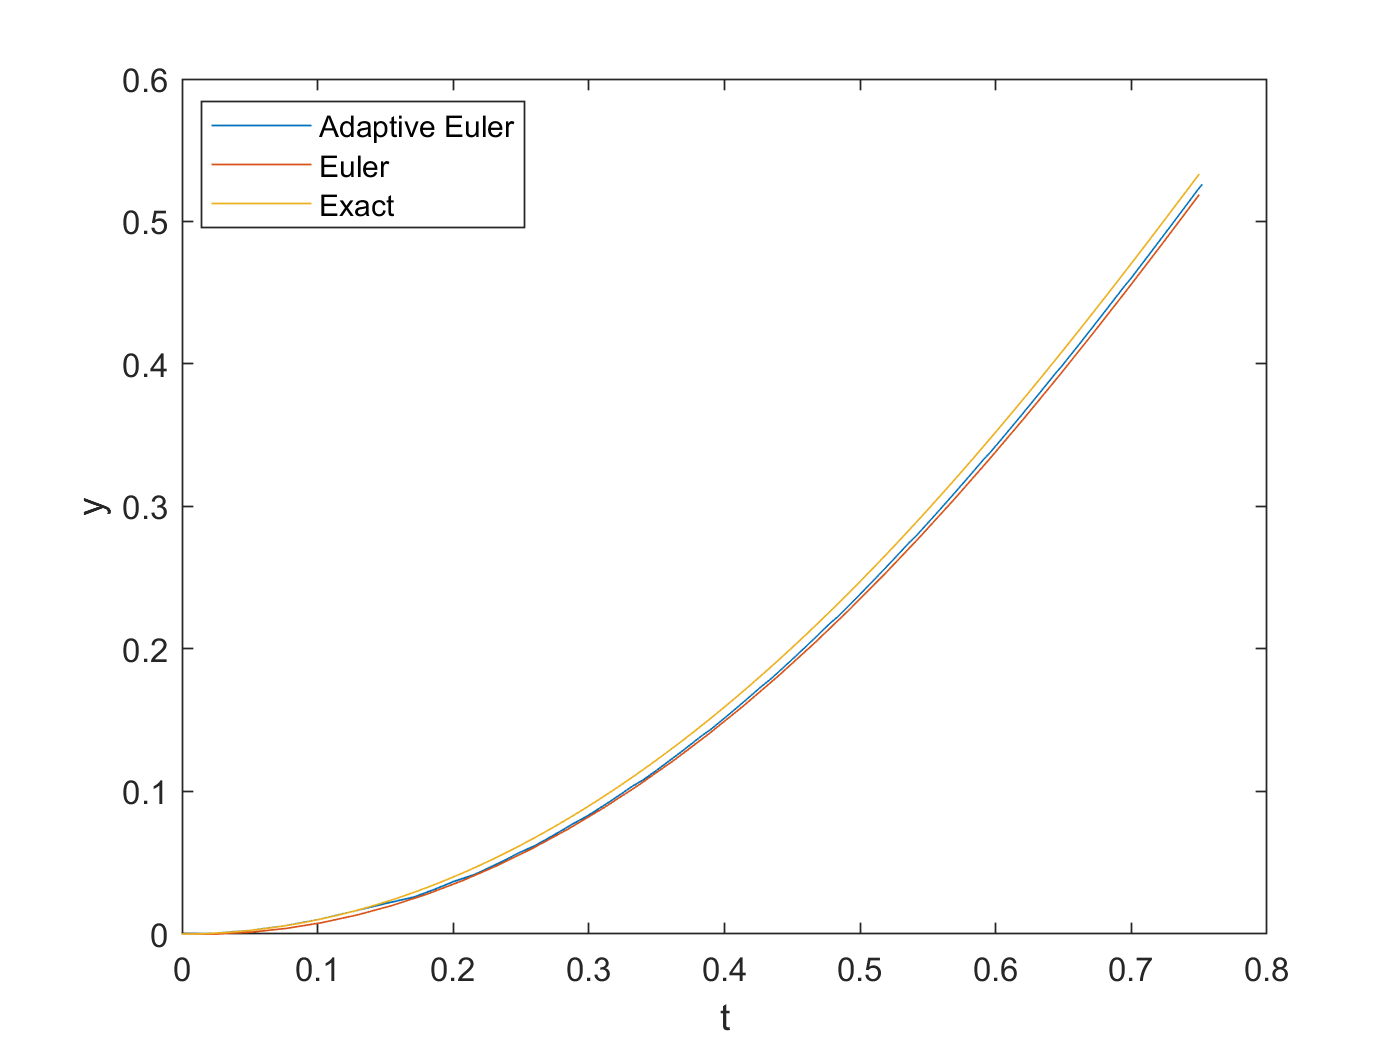

g_5c = @(t) sin(t.^2);
tt_5c = linspace(0, 0.75, 100);
yy_5c = g_5c(tt_5c);

plot(soln_5b_x, soln_5b_y, t_5a, soln5a, tt_5c, yy_5c);
xlabel("t");
ylabel("y");
legend("Adaptive Euler", "Euler", "Exact", 'Location', "Best")

## Exercise 6

Objective: Problems with Numerical Methods.

Details: Consider the IVP from exercise 3 (and 5).

(a) From the two approximations calculated in exercise 5, which one is closer to the actual solution (done in 3.b)? Explain why.

The adaptive euler is closer because the step size is decreasing as the error passes the tolerance. This means that the global error, En, is also smaller since En is quadratic with respect to the time step but linear with respect to number of steps.

(b) Plot the exact solution (from exercise 3.b), the Euler's approximation (from exercise 3.a) and the adaptive Euler's approximation (from exercise 5) from `t=0` to `t=1.5`.

f6b = @(t,y) 2 .* t .* sqrt( 1 - y.^2 );
t_6b = linspace(0, 1.5, 30);
soln6b = euler(f6b, 0, t_6b);

[soln_6b_x, soln_6b_y] = f4(f5a, 0, 1.5, 0, 0.025)

soln_6b_x =          0    0.0250    0.0500    0.0750    0.1000    0.1250    0.1500    0.1712    0.1859    0.2005    0.2152    0.2265    0.2378    0.2491    0.2604    0.2699    0.2795    0.2890    0.2986    0.3069    0.3152    0.3236    0.3319    0.3403    0.3473    0.3544    0.3615    0.3685    0.3756    0.3826    0.3897    0.3959    0.4022    0.4084    0.4147    0.4209    0.4272    0.4334    0.4390    0.4445    0.4501    0.4556    0.4612    0.4667    0.4723    0.4778    0.4834    0.4882    0.4930    0.4978


soln_6b_y =    0.0000 + 0.0000i   0.0006 + 0.0000i   0.0025 + 0.0000i   0.0056 + 0.0000i   0.0100 + 0.0000i   0.0156 + 0.0000i   0.0214 + 0.0000i   0.0260 + 0.0000i   0.0312 + 0.0000i   0.0369 + 0.0000i   0.0415 + 0.0000i   0.0465 + 0.0000i   0.0518 + 0.0000i   0.0572 + 0.0000i   0.0621 + 0.0000i   0.0671 + 0.0000i   0.0724 + 0.0000i   0.0778 + 0.0000i   0.0827 + 0.0000i   0.0877 + 0.0000i   0.0929 + 0.0000i   0.0982 + 0.0000i   0.1036 + 0.0000i   0.1083 + 0.0000i   0.1131 + 0.0000i   0.1181 + 0.0000i   0.1231 + 0.0000i   0.1282 + 0.0000i   0.1334 + 0.0000i   0.1387 + 0.0000i   0.1435 + 0.0000i   0.1483 + 0.0000i   0.1533 + 0.0000i   0.1583 + 0.0000i   0.1633 + 0.0000i   0.1685 + 0.0000i   0.1737 + 0.0000i   0.1784 + 0.0000i   0.1832 + 0.0000i   0.1880 + 0.0000i   0.1929 + 0.0000i   0.1978 + 0.0000i   0.2028 + 0.0000i   0.2078 + 0.0000i   0.2129 + 0.0000i   0.2180 + 0.0000i   0.2225 + 0.0000i   0.2271 + 0.0000i   0.2317 + 0.0000i   0.2363 + 0.0000i



g_6b = @(t) sin(t.^2);
tt_6b = linspace(0, 1.5, 100);
yy_6b = g_6b(tt_6b);

plot(soln_6b_x, soln_6b_y, t_6b, soln6b, tt_6b, yy_6b);

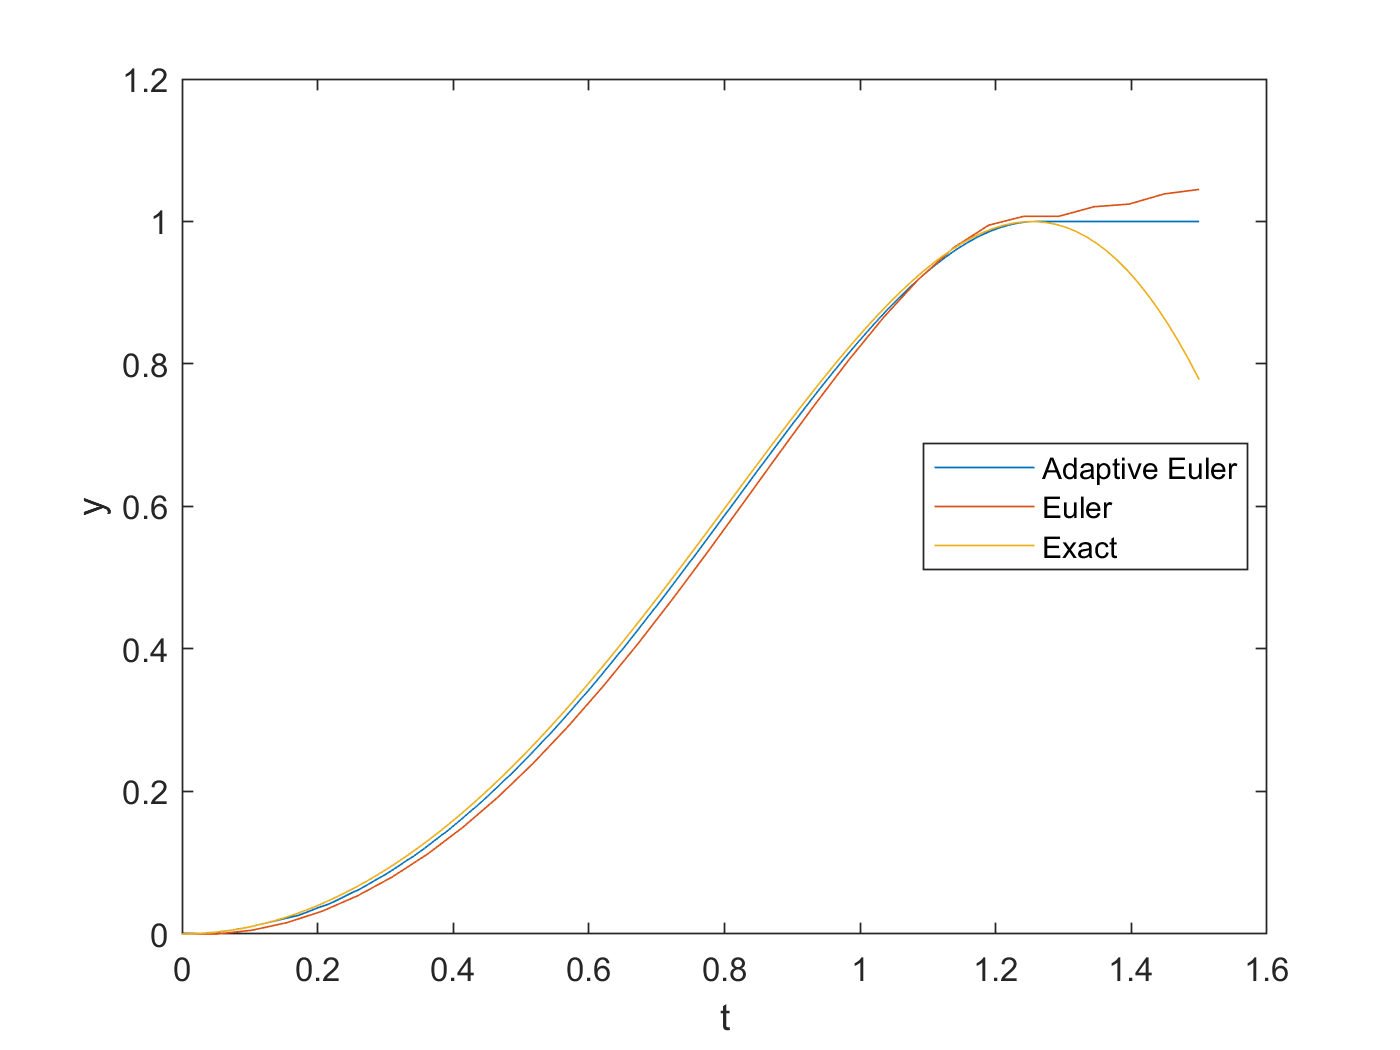

xlabel("t");
ylabel("y");
legend("Adaptive Euler", "Euler", "Exact", 'Location', "Best")

(c) Notice how the exact solution and the approximations become very different. Why is that? Write your answer as a comment.

If you follow the differential equation, once the slope hits 0 it continues to follow 0, that is to say every solution of this function has slope 0 along that particular line. If we were to draw a phase plot of this function, we would see continuous lines at y = 1. This means the function becomes stuck at when the slope is 0 because every time it probes forward it finds slope 0 and continues tracking that line